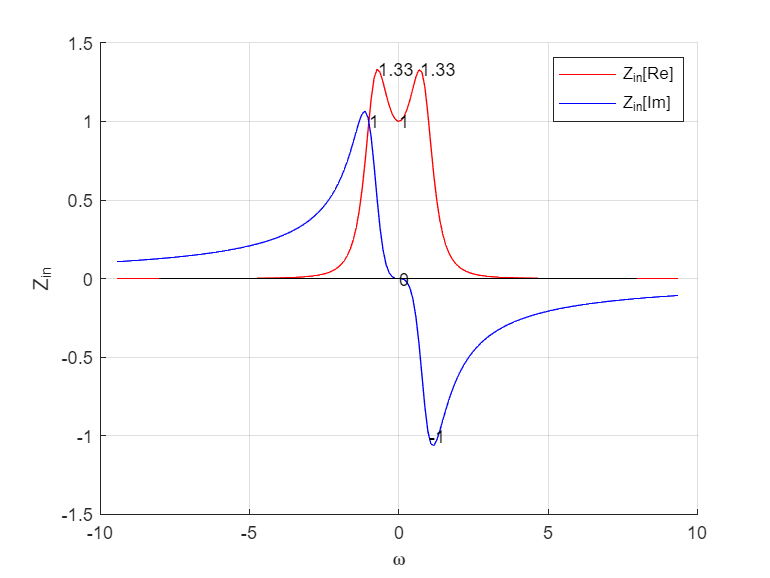

%取R=1Ω，L=1H，C=1F
x = -3*pi:0.1:3*pi;
y3 = @(x)0;
y1 = @(x)(x.^2 + (x.^2-1).^2).^(-1);
y2 = @(x)(-1.*x.^3).*(x.^2 + (x.^2-1).^2).^(-1);
hold on;
li1 = plot(x,y1(x),'r-');
li2 = plot(x,y2(x),'b-');
legend([li1,li2],{'Z_{in}[Re]','Z_{in}[Im]'})
li3 = plot([-8,8],[0,0],'k-','HandleVisibility','off');
xlabel('\omega')
ylabel('Z_{in}')
%实部极值，通过Mathematica计算得到
text(0,y1(0),num2str(y1(0)))
text((-1)*sqrt(2)^(-1),y1((-1)*sqrt(2)^(-1)),num2str(roundn(y1((-1)*sqrt(2)^(-1)),-2)))
text(sqrt(2)^(-1),y1(sqrt(2)^(-1)),num2str(roundn(y1(sqrt(2)^(-1)),-2)))
%虚部极值，通过Mathematica计算得到
text(0,y2(0),num2str(y2(0)))
text((-1),y2(-1),num2str(roundn(y2(-1),-2)))
text(1,y2(1),num2str(roundn(y2(1),-2)))
grid on
hold off